# Introduction to Synthetic Aperture Radar Using Python and MATLAB

## by Andy Harrison - © 2022 Artech House

### Example 7.6.3 Noise Equivalent Sigma Zero

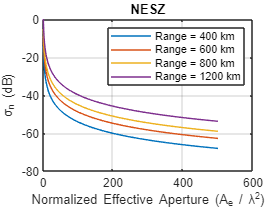

clear

% Set the temperature (K)
T = 290;

% Boltzmann's constant
k = 1.380649e-23;

% Noise figure
F = 2;

% Losses
L = 2;

% Operating frequency (Hz)
frequency = 9.65e9;

% Calculate the wavelength (m)
wavelength = 299792458 / frequency;

% Effective velocity (m/s)
v = 7.8e3;

% Range resolution (m)
delta_range = 0.5;

% Average transmitted power (W)
pav = 320;

% Set the normalized effective aperture (m^2)
effective_aperture_normalized = linspace(1, 500, 500);

r = 400e3; nesz(1,:) =  8 * pi * wavelength * r^3 * k * v * T * F * L ./ (pav * effective_aperture_normalized.^2 * delta_range);

r = 600e3; nesz(2,:) =  8 * pi * wavelength * r^3 * k * v * T * F * L ./ (pav * effective_aperture_normalized.^2 * delta_range);

r = 800e3; nesz(3,:) =  8 * pi * wavelength * r^3 * k * v * T * F * L ./ (pav * effective_aperture_normalized.^2 * delta_range);

r = 1200e3; nesz(4,:) = 8 * pi * wavelength * r^3 * k * v * T * F * L ./ (pav * effective_aperture_normalized.^2 * delta_range);


% Plot the NESZ
figure;
plot(effective_aperture_normalized, 10 * log10(nesz))
title('NESZ')
xlabel('Normalized Effective Aperture (A_e / \lambda^2)')
ylabel('\sigma_n (dB)')
grid on
legend('Range = 400 km', 'Range = 600 km', 'Range = 800 km', 'Range = 1200 km');

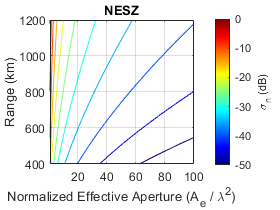


% Set the range
r = linspace(400e3, 1200e3, 500);

% Reset the effective normalized aperture
effective_aperture_normalized = linspace(1, 100, 500);

% Create grid for range and aperture
[rr, aa] = meshgrid(r, effective_aperture_normalized);

% Calculate NESZ
nesz = 8 * pi * wavelength * rr.^3 *v *  k * T * F * L ./ (pav * aa.^2 * delta_range);

% Plot the results
figure;
contour(aa, rr/1e3, 10 * log10(nesz)); shading flat
colormap jet
a = colorbar;
a.Label.String = '\sigma_n (dB)';
title('NESZ')
xlabel('Normalized Effective Aperture (A_e / \lambda^2)')
ylabel('Range (km)')
grid on